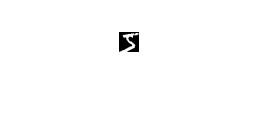

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 20, 0);
imshow(ims(:,:,1))

labels(1)

ans = 5

Agafar el 80% com a mostra i 20% per testejar el model

% [rows, cols, nims] = size(ims)

rows = 20

cols = 20

nims = 2000

% sample = ims(:,:, 1:floor(nims*0.8));
% test = ims(:,:, floor(nims*0.8)+1:end);

data = regionprops(ims(:,:,1), 'all');

data = struct with fields:
                   Area: 1
               Centroid: [18 2]
            BoundingBox: [17.5000 1.5000 1 1]
            SubarrayIdx: {[2]  [18]}
        MajorAxisLength: 1.1547
        MinorAxisLength: 1.1547
           Eccentricity: 0
            Orientation: 0
             ConvexHull: [5×2 double]
            ConvexImage: 1
             ConvexArea: 1
            Circularity: Inf
                  Image: 1
            FilledImage: 1
             FilledArea: 1
            EulerNumber: 1
                Extrema: [8×2 double]
          EquivDiameter: 1.1284
               Solidity: 1
                 Extent: 1
           PixelIdxList: 342
              PixelList: [18 2]
              Perimeter: 0
           PerimeterOld: 0
       MaxFeretDiameter: 1.4142
          MaxFeretAngle: 135
    MaxFeretCoordinates: [2×2 double]
       MinFeretDiameter: 1
          MinFeretAngle: -90
    MinFeretCoordinates: [2×2 double]


data2 = regionprops(ims(:,:,2), 'all');

data2 = struct with fields:
                   Area: 2
               Centroid: [17 8.5000]
            BoundingBox: [16.5000 5.5000 1 6]
            SubarrayIdx: {[6 7 8 9 10 11]  [17]}
        MajorAxisLength: 10.0664
        MinorAxisLength: 1.1547
           Eccentricity: 0.9934
            Orientation: 90
             ConvexHull: [7×2 double]
            ConvexImage: [6×1 logical]
             ConvexArea: 6
            Circularity: Inf
                  Image: [6×1 logical]
            FilledImage: [6×1 logical]
             FilledArea: 2
            EulerNumber: 2
                Extrema: [8×2 double]
          EquivDiameter: 1.5958
               Solidity: 0.3333
                 Extent: 0.3333
           PixelIdxList: [2×1 double]
              PixelList: [2×2 double]
              Perimeter: 0
           PerimeterOld: 0
       MaxFeretDiameter: 6.0828
          MaxFeretAngle: 99.4623
    MaxFeretCoordinates: [2×2 double]
       MinFeretDiameter: 1
          MinFeretAngle: 0
  

size(ims, 3)

ans = 2000

[ims, labels] = readMNIST('train-images-idx3-ubyte', 'train-labels-idx1-ubyte', 2000, 0);
areas = [];
centroids = [];
boundingBoxes = [];
%Features millor pensades, no les 3 primeres
eccentricities = [];


eccentricities =

     []



majorAxis = [];


majorAxis =

     []



minorAxis = [];


minorAxis =

     []



orientation = [];


orientation =

     []



perimeter = [];


perimeter =

     []




for im=1:size(ims, 3)
    data = regionprops(ims(:,:,im), 'all');
    areas = [areas;data.Area];
    centroids = [centroids;data.Centroid];
    boundingBoxes = [boundingBoxes;data.BoundingBox];
    eccentricities = [eccentricities; data.Eccentricity];
    majorAxis = [majorAxis; data.MajorAxisLength];
    minorAxis = [minorAxis; data.MinorAxisLength];
    orientation = [orientation; data.Orientation];
    perimeter = [perimeter; data.Perimeter];
end

t = table(areas, centroids, boundingBoxes, eccentricities, majorAxis, minorAxis, orientation, perimeter, labels(1:size(areas, 1)));